# **Modélisation mathématiques du dirigeable**

clc; clear;

## Données :

g = 9.80665;
rho = 1.225;
diameter = 12.7*10^(-2);
radius = diameter/2;
m_struct = 3;
v_struct = 7;
key = ["gravity", "rho", "diameter", "m_struct", "v_struct"];
value = [g, rho, diameter, m_struct, v_struct];
data = containers.Map(key, value);

% Axes du dirigeable
x_m = [1; 0; 0];
y_m = [0; 1; 0];
z_m = [0; 0; 1];

key_axes_m = {'x_m', 'y_m', 'z_m'};
value_axes_m = {x_m, y_m, z_m};
data_axes = containers.Map(key_axes_m, value_axes_m);

% angle du servomoteur
angle = 0;

## Import workbench data

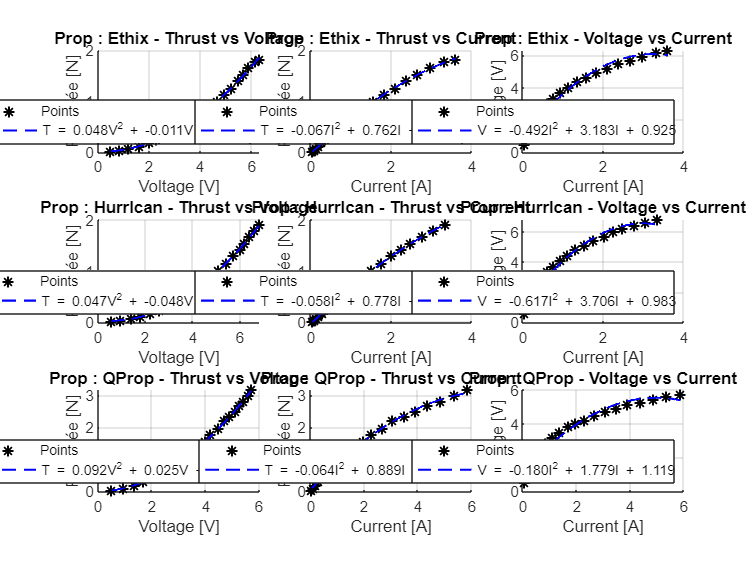


% Définir le répertoire de travail courant
current_folder = pwd;
data_folder = fullfile(current_folder, 'data');
test_Bench_data = load(fullfile(data_folder, "testBench_motor.mat"));

% Structure pour stocker les coefficients
coefficients = struct();

PropName = ["Ethix", "HurrIcan", "QProp"];
coefficients = FindInterpCoeff(PropName, g, test_Bench_data, coefficients);


output_file = fullfile(data_folder, 'coefficients.mat');
save(output_file, 'coefficients');


## Classe MotorSimulation

voltage_value = 4

voltage_value = 4

MotSim = MotorSimulation(PropName(1), coefficients, angle, data_axes, voltage_value)

MotSim =   MotorSimulation with properties:

      MotorName: "Ethix"
          Coeff: [1×1 struct]
       AngleRot: 0
           Axes: [3×1 containers.Map]
    InterpCoeff: [0.0482 -0.0106 0.0091 0.5000 6.3000]
        Voltage: 4


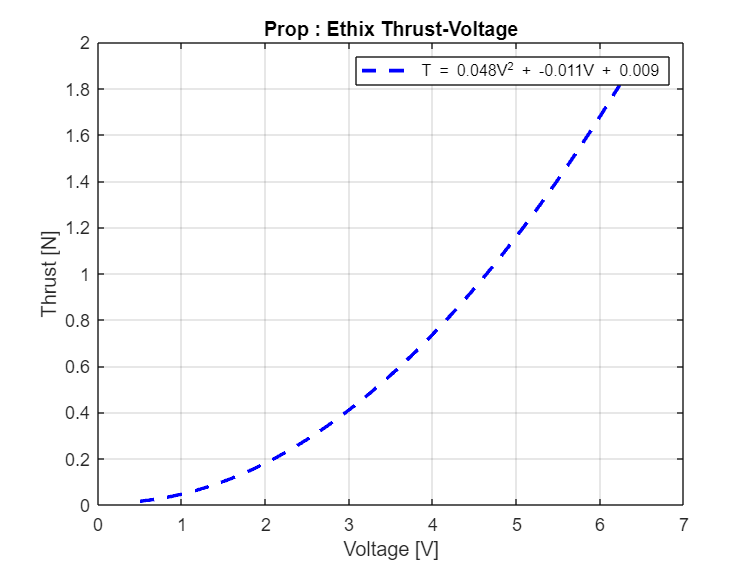

MotSim.plot_data()

Rotation = MotSim.Rotation()

Rotation =      1     0     0
     0     1     0
     0     0     1



F_thrust = MotSim.ForceExpression()

F_thrust =          0
         0
    0.7382


## Classe Dirigeable

box_keys = ["x_box_1", "x_box_2","y_box_1","y_box_2","z_box"];
box_values = [2.2, 1.8, 0.5, 0.7, 0.1];
box_containers = containers.Map(box_keys, box_values);

tube_keys = ["x_T_1", "x_T_2", "y_T_1", "y_T_2", "z_T"];
tube_values = [2.02, 1.98, 0.7, 0.9, 0.02];
tube_containers = containers.Map(tube_keys, tube_values)

tube_containers =   Map with properties:

        Count: 5
      KeyType: char
    ValueType: double



motor_key = ["x_mot_1", "x_mot_2", "y_mot_1", "y_mot_2", "z_mot"];
motor_values = [2.1, 1.9, 0.9, 1.1, 0.05];
motor_containers = containers.Map(motor_key, motor_values);

keys = {'box_containers', 'tube_containers', 'motor_containers'};
values = {box_containers, tube_containers, motor_containers};
simu_containers = containers.Map(keys, values);

## Tentaive rotation

PivotMot = [
    [2 0 0]; % moteur avant
    [2 0 0]; % moteur avant
    [-2 0 0]; % moteur arrière
    [-2 0 0]; % moteur arrière
    ];

ThetaVec = [-pi/4, -pi/4, -pi/2, -pi/2];

D = Dirigeable(data, data_axes, angle, simu_containers, PivotMot, ThetaVec)

D =   Dirigeable with properties:

              Data: [5×1 containers.Map]
              Axes: [3×1 containers.Map]
             Angle: 0
          PivotMot: [4×3 double]
             Theta: [-0.7854 -0.7854 -1.5708 -1.5708]
    SimuContainers: [3×1 containers.Map]



W = D.weight()

W =          0
         0
  -29.4200


B = D.Buoyancy()

B =          0
         0
   84.0920


   8-------7

  /|      /|

 4-------3 |

 | |     | |

 | 5-----|-6

 |/      |/

 1-------2

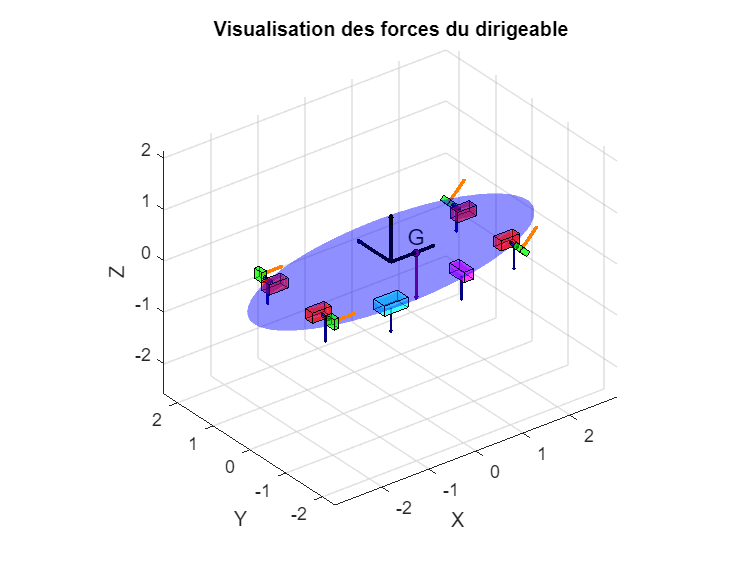

D.plot()